## Kinematic analysis of the thumb

### Start of program with initialization of lengths, angles

clear
clc

table = readtable('linkage_model_data.xlsx');
params = table2array(table(1:43, 7));

[l_01, l_12, l_23, l_30, l_24, l_34, l_45, l_56, l_67, l_73, l_68, l_M8, l_MS, l_59, l_910, l_911, l_1112, l_1113, l_MP, l_PD, l_DF, l_810, l_10P, l_P12, l_D13, l_D12, l_F13, h_0, h_3, h_7, alpha1, alpha2, alpha3, alpha4, beta1, l_M0, l_M3, theta_M0, theta_M3, theta_MS, l_7S, l_M10, l_P8] ...
    = feval(@(x) x{:}, num2cell(params.'));

params = table2array(table(1:19, 12));
[l_01_, l_12_, l_23_, l_24_, l_34_, l_45_, d_p5_k_, h_0_, h_3_, l_M0_, l_M3_, theta_M0_, theta_M3_, z_p, lk_MP5, lk_PP5] ...
    = feval(@(x) x{:}, num2cell(params.'));

alpha1  = alpha1 * pi/180;
alpha2  = alpha2 * pi/180;
alpha3  = alpha3 * pi/180;
beta1   = beta1 * pi/180;
alpha4  = alpha4 * pi/180;

%e = [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];
%e = [2.2,1.6,0.4,1.8,3.6,0.5,0.4,-0.4,1.8,1,-0.6,1.6,1.8,0.2,1.4,0,0];
%e = [2.2,1.6,0.4,1.8,3.6,2.4,0.4,-0.6,1.8,1,-0.6,4.4,1.8,-0.6,1.4,0.4,1.8];
e = [2.2,1.6,0.4,1.8,4.8,2.4,0.4,-0.6,2.2,1,-0.6,4.8,2.2,-0.6,1.4,0.4,1.8];

l_67 = l_67 + e(1);
l_68 = l_68 + e(2);
l_56 = l_56 + e(3);
l_59 = l_59 + e(4);
l_45_ = l_45_ + e(5);
l_24_ = l_24_ + e(6);
l_34_ = l_34_ + e(7);
l_23_ = l_23_ + e(8);
l_45 = l_45 + e(9);
l_910 = l_910 + e(10);
l_911 = l_911 + e(11);
l_24 = l_24 + e(12);
l_34 = l_34 + e(13);
l_23 = l_23 + e(14);
l_1112 = l_1112 + e(15);
l_1113 = l_1113 - e(15);
l_12 = l_12 + e(16);
l_12_ = l_12_ + e(17);

### Input parameters

steps = 50;
steps2 = 50;
theta0 = [];
theta0_ = [];

theta1_max = 50;
theta1 = linspace(0, theta1_max, steps);
theta2 = linspace(0, theta1_max * 5/4, steps);
theta3 = linspace(0, theta1_max * 2/4, steps);

theta1_ = linspace(-30, 30, steps2);

A = [1, 0, 0, 0;
    0, 1, 0, 0;
    0, 0, 1, 0];
A_T = A.';

### Fixed joints

M_h = [0; 0; 0; 1];

M = [0; 0; 0];
K_0 = A * (rot(0, theta_M0 * pi/180, 0) * trans(l_M0, 0, 0) * M_h);
K_3 = A * (rot(0, theta_M3 * pi/180, 0) * trans(l_M3, 0, 0) * M_h);
S = A * (rot(0, theta_MS * pi/180, 0) * trans(l_MS, 0, 0) * M_h);

P_0 = A * (rot(0, 0, theta_M0_ * pi/180) * trans(l_M0_, 0, 0) * M_h) + [0; 0; z_p];
P_3 = A * (rot(0, 0, theta_M3_ * pi/180) * trans(l_M3_, 0, 0) * M_h) + [0; 0; z_p];

### Forward kinematic analysis

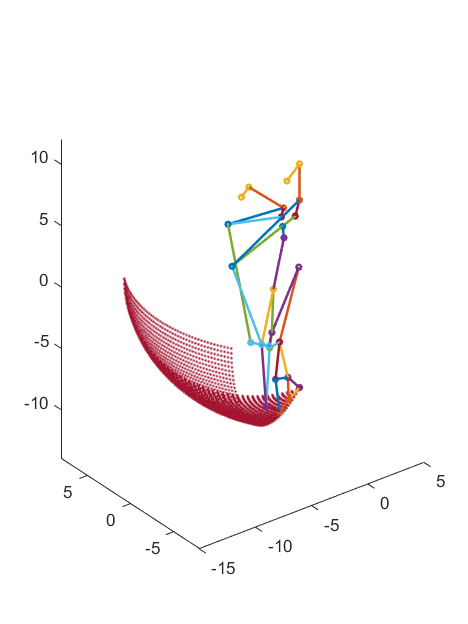

x = [];
y = [];
z = [];
index = 0;

row = 0;
column = 0;

f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 9.9, 13.2]);
for j = 1:steps2
    count1 = 0;
    count2 = 0;
    column = column + 1;
    row = 0;
    for i = 1:steps
        thetaMP = theta1(i) * pi/180;
        thetaPD = (theta1(i) + theta2(i)) * pi/180;
        thetaDF = (theta1(i) + theta2(i) + theta3(i)) * pi/180;
        P = -l_MP * [cos(thetaMP); 0; sin(thetaMP)];
        D = P - l_PD * [cos(thetaPD); 0; sin(thetaPD)];
        F = D - l_DF * [cos(thetaDF); 0; sin(thetaDF)];
        
        K_8 = circle_circle_xz(M, P, l_M8, l_P8, +1);
        K_10 = circle_circle_xz(M, P, l_M10, l_10P, +1);
        K_12 = circle_circle_xz(P, D, l_P12, l_D12, +1);
        K_13 = circle_circle_xz(D, F, l_D13, l_F13, +1);
        
        K_11 = circle_circle_xz(K_13, K_12, l_1113, l_1112, -1);
        K_9 = circle_circle_xz(K_11, K_10, l_911, l_910, -1);
        
        S_ = A * (rot(0, 0, -theta1_(j) * pi/180) * [S; 1]);
        K_7 = [S_(1) - sqrt(l_7S^2 - S_(2)^2); 0; h_7];
        
        K_6 = circle_circle_xz(K_7, K_8, l_67, l_68, +1);
        K_5 = circle_circle_xz(K_6, K_9, l_56, l_59, +1);
        
        P_5p = circle_circle_xz(M, P, lk_MP5, lk_PP5, +1);
        
        P_5p = A * (rot(0, 0, theta1_(j) * pi/180) * [P_5p; 1]);
        P    = A * (rot(0, 0, theta1_(j) * pi/180) * [P; 1]);
        D    = A * (rot(0, 0, theta1_(j) * pi/180) * [D; 1]);
        F    = A * (rot(0, 0, theta1_(j) * pi/180) * [F; 1]);
        K_5  = A * (rot(0, 0, theta1_(j) * pi/180) * [K_5; 1]);
        K_6  = A * (rot(0, 0, theta1_(j) * pi/180) * [K_6; 1]);
        K_7  = A * (rot(0, 0, theta1_(j) * pi/180) * [K_7; 1]);
        K_8  = A * (rot(0, 0, theta1_(j) * pi/180) * [K_8; 1]);
        K_9  = A * (rot(0, 0, theta1_(j) * pi/180) * [K_9; 1]);
        K_10 = A * (rot(0, 0, theta1_(j) * pi/180) * [K_10; 1]);
        K_11 = A * (rot(0, 0, theta1_(j) * pi/180) * [K_11; 1]);
        K_12 = A * (rot(0, 0, theta1_(j) * pi/180) * [K_12; 1]);
        K_13 = A * (rot(0, 0, theta1_(j) * pi/180) * [K_13; 1]);
        
        P_5 = P_5p + d_p5_k_ * [-sin(theta1_(j) * pi/180); cos(theta1_(j) * pi/180); 0];
        
        K_4 = circle_circle_xz([K_5(1); 0; K_5(3)], K_3, sqrt(l_45^2 - K_5(2)^2), l_34, -1);
        
        K_2 = circle_circle_xz(K_3, K_4, l_23, l_24, +1);
        K_1 = circle_circle_xz(K_0, K_2, l_01, l_12, -1);
        
        row = row + 1;
        
        v_10 = K_1 - K_0;
        theta0(row, column) = atan2(v_10(3), sqrt(v_10(1)^2 + v_10(2)^2)) * 180/pi;
        
        P_4 = circle_circle_xy( [P_5(1); P_5(2); 0], P_3, sqrt( l_45_^2 - (z_p-P_5(3))^2 ), l_34_, -1) + [0; 0; z_p];
        P_2 = circle_circle_xy(P_4, P_3, l_24_, l_23_, -1) + [0; 0; z_p];
        P_1 = circle_circle_xy(P_2, P_0, l_12_, l_01_, +1) + [0; 0; z_p];
        
        v_10_ = P_1 - P_0;
        theta0_(row, column) = atan2(v_10_(2), v_10_(1)) * 180/pi;
        
        linkS7   = [S   , K_7];
        linkMP   = [M   , P];
        linkPD   = [P   , D];
        linkDF   = [D   , F];
        linkM8   = [M   , K_8];
        link810  = [K_8 , K_10];
        link10P  = [K_10, P];
        linkP12  = [P   , K_12];
        link12D  = [K_12, D];
        linkD13  = [D   , K_13];
        link13F  = [K_13, F];
        link67   = [K_6 , K_7];
        link68   = [K_6 , K_8];
        link910  = [K_9 , K_10];
        link911  = [K_9 , K_11];
        link1112 = [K_11, K_12];
        link1113 = [K_11, K_13];
        link56   = [K_5 , K_6];
        link59   = [K_5 , K_9];
        link34   = [K_3 , K_4];
        link45   = [K_4 , K_5];
        link23   = [K_2 , K_3];
        link24   = [K_2 , K_4];
        link12   = [K_1 , K_2];
        link01   = [K_0 , K_1];
        
        link_k_P5 = [P_5p, P_5];
        link_K8_P5p = [K_8, P_5p];
        link_K10_P5p = [K_10, P_5p];
        link45_ = [P_4, P_5];
        link34_ = [P_3, P_4];
        link23_ = [P_2, P_3];
        link24_ = [P_2, P_4];
        link12_ = [P_1, P_2];
        link01_ = [P_0, P_1];
        
        if ~isreal(v_10)
            count1 = count1 + 1;
            if count1 == 1
                fprintf("theta1 = %d, theta1_ = %d\n", theta1(i - 1), theta1_(j));
            end
            break;
        end
        
        if ~isreal(v_10_)
            count2 = count2 + 1;
            if count2 == 1
                fprintf("theta1 = %d, theta1_ = %d\n", theta1(i - 1), theta1_(j));
            end
            break;
        end
        
        index = index + 1;
        x(index) = F(1);
        y(index) = F(2);
        z(index) = F(3);
        
        p = plot3(linkS7(1, :),   linkS7(2, :),   linkS7(3, :),   '-o', ...
            linkMP(1, :),   linkMP(2, :),   linkMP(3, :),   '-o', ...
            linkPD(1, :),   linkPD(2, :),   linkPD(3, :),   '-o', ...
            linkM8(1, :),   linkM8(2, :),   linkM8(3, :),   '-o', ...
            link810(1, :),  link810(2, :),  link810(3, :),  '-o', ...
            link10P(1, :),  link10P(2, :),  link10P(3, :),  '-o', ...
            linkP12(1, :),  linkP12(2, :),  linkP12(3, :),  '-o', ...
            link12D(1, :),  link12D(2, :),  link12D(3, :),  '-o', ...
            linkD13(1, :),  linkD13(2, :),  linkD13(3, :),  '-o', ...
            link13F(1, :),  link13F(2, :),  link13F(3, :),  '-o', ...
            link67(1, :),   link67(2, :),   link67(3, :),   '-o', ...
            link68(1, :),   link68(2, :),   link68(3, :),   '-o', ...
            link910(1, :),  link910(2, :),  link910(3, :),  '-o', ...
            link911(1, :),  link911(2, :),  link911(3, :),  '-o', ...
            link1112(1, :), link1112(2, :), link1112(3, :), '-o', ...
            link1113(1, :), link1113(2, :), link1113(3, :), '-o', ...
            link56(1, :),   link56(2, :),   link56(3, :),   '-o', ...
            link59(1, :),   link59(2, :),   link59(3, :),   '-o', ...
            link34(1, :),   link34(2, :),   link34(3, :),   '-o', ...
            link45(1, :),   link45(2, :),   link45(3, :),   '-o', ...
            link23(1, :),   link23(2, :),   link23(3, :),   '-o', ...
            link24(1, :),   link24(2, :),   link24(3, :),   '-o', ...
            link12(1, :),   link12(2, :),   link12(3, :),   '-o', ...
            link01(1, :),   link01(2, :),   link01(3, :),   '-o', ...
            linkDF(1, :),   linkDF(2, :),   linkDF(3, :),   '-o', ...
            link45_(1,:),   link45_(2,:),   link45_(3,:),   '-o', ...
            link34_(1,:),   link34_(2,:),   link34_(3,:),   '-o', ...
            link23_(1,:),   link23_(2,:),   link23_(3,:),   '-o', ...
            link24_(1,:),   link24_(2,:),   link24_(3,:),   '-o', ...
            link12_(1,:),   link12_(2,:),   link12_(3,:),   '-o', ...
            link01_(1,:),   link01_(2,:),   link01_(3,:),   '-o', ...
            link_K8_P5p(1,:), link_K8_P5p(2,:), link_K8_P5p(3,:), '-o', ...
            link_K10_P5p(1,:), link_K10_P5p(2,:), link_K10_P5p(3,:), '-o', ...
            link_k_P5(1,:), link_k_P5(2,:), link_k_P5(3,:), '-o', ...
            x, y, z, '.', 'MarkerSize', 3, 'LineWidth', 1.5  );
        daspect([1 1 1]);
        xlim([-15 5]);
        ylim([-8 8]);
        zlim([-14 12]);
        %view([0 0 1]); % top-view
        %view([0 -1 0]); % front-view
        %view([0 -0.5 0.5]);
        %view([1 0 0]); % right-view
        %view([0 1 0]); % back-view
        if (j == 1) && (i == 1)
            pause(4);
        end
        pause(0.001);
    end
    pause(0.005);
end
exportgraphics(f, 'thumb/figures/thumb-workspace.png', 'Resolution', 600);

### Plotting forward kinematics results

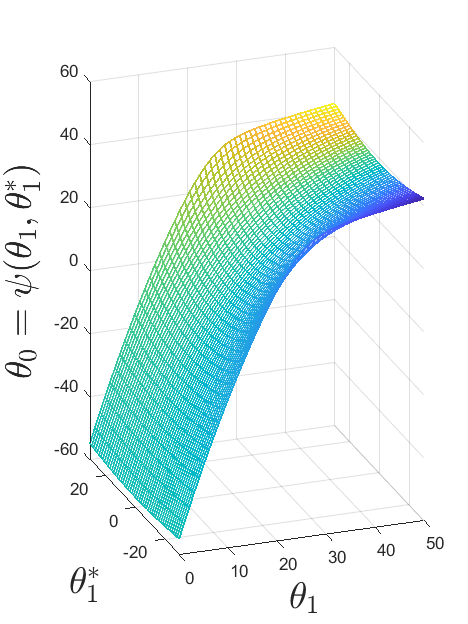

extraInputs = {'interpreter','latex','fontsize',22}; % name, value pairs

[X,Y] = meshgrid(theta1, theta1_);
C = X.*Y;
f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 9.9, 13.2]);
p = mesh(theta1, theta1_, theta0.', C);
hold on
%p2 = surf(theta1, theta1_, query_theta0.', C);
p.FaceAlpha = 0.5;
p.LineWidth = 1;
ylim([theta1_(1) theta1_(end)]);
xlim([theta1(1) theta1(end)]);
%daspect([0.5 0.4 0.5]);
%view([0 -1 0]); % front-view
view([-20 15]);
xlabel('$\theta_1$', extraInputs{:});
ylabel('$\theta_1^*$', extraInputs{:});
zlabel('$\theta_0 = \psi(\theta_1, \theta_1^*)$', extraInputs{:});
exportgraphics(f, 'thumb/figures/theta0_step12_iso.png', 'Resolution', 600);

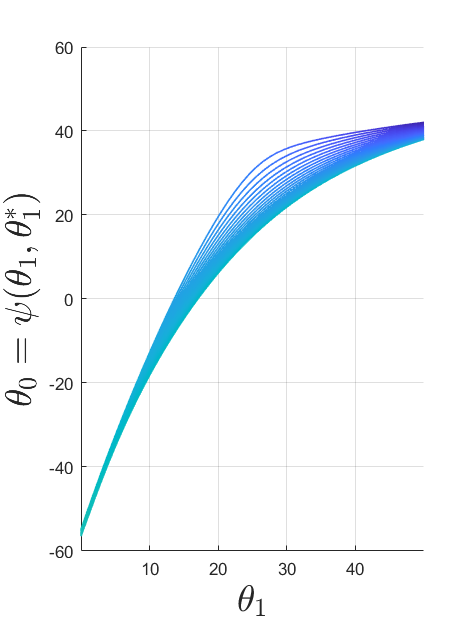

[X,Y] = meshgrid(theta1, theta1_);
C = X.*Y;
f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 9.9, 13.2]);
p = waterfall(theta1, theta1_, theta0.', C);
p.FaceAlpha = 0;
p.LineWidth = 1;
ylim([theta1_(1) theta1_(end)]);
xlim([theta1(1)+0.01 theta1(end)-0.01]);
view([0 -1 0]); % front-view
xlabel('$\theta_1$', extraInputs{:});
ylabel('$\theta_1^*$', extraInputs{:});
zlabel('$\theta_0 = \psi(\theta_1, \theta_1^*)$', extraInputs{:});
exportgraphics(f, 'thumb/figures/theta0_step12_front.png', 'Resolution', 600);

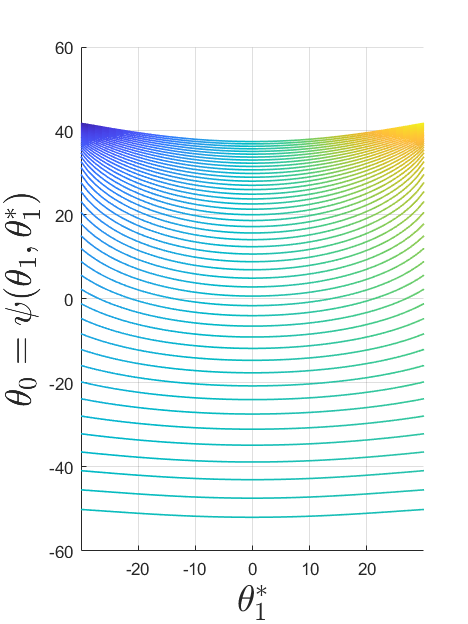

[X,Y] = meshgrid(theta1_, theta1);
C = X.*Y;
f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 9.9, 13.2]);
p = waterfall(theta1_, theta1, theta0, C);
p.FaceAlpha = 0.0;
p.LineWidth = 1;
xlim([theta1_(1)+0.01 theta1_(end)-0.01]);
ylim([theta1(1)+0.01 theta1(end)-0.01]);
view([0 -1 0]); % front-view
ylabel('$\theta_1$', extraInputs{:});
xlabel('$\theta_1^*$', extraInputs{:});
zlabel('$\theta_0 = \psi(\theta_1, \theta_1^*)$', extraInputs{:});
exportgraphics(f, 'thumb/figures/theta0_step12_right.png', 'Resolution', 600);

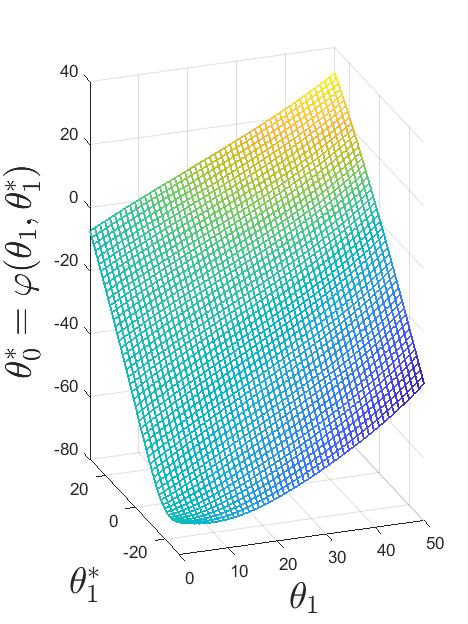

[X,Y] = meshgrid(theta1, theta1_);
C = X.*Y;
f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 9.9, 13.2]);
p = mesh(theta1, theta1_, theta0_.', C);
hold on
%p2 = surf(theta1, theta1_, query_theta0_.', C);
p.FaceAlpha = 0.05;
p.LineWidth = 1;
ylim([theta1_(1) theta1_(end)]);
xlim([theta1(1) theta1(end)]);
%daspect([0.5 0.4 0.5]);
%view([0 -1 0]); % front-view
view([-20 15]);
xlabel('$\theta_1$', extraInputs{:});
ylabel('$\theta_1^*$', extraInputs{:});
zlabel('$\theta_0^* = \varphi(\theta_1, \theta_1^*)$', extraInputs{:});
exportgraphics(f, 'thumb/figures/theta0--_step12_iso.png', 'Resolution', 600);

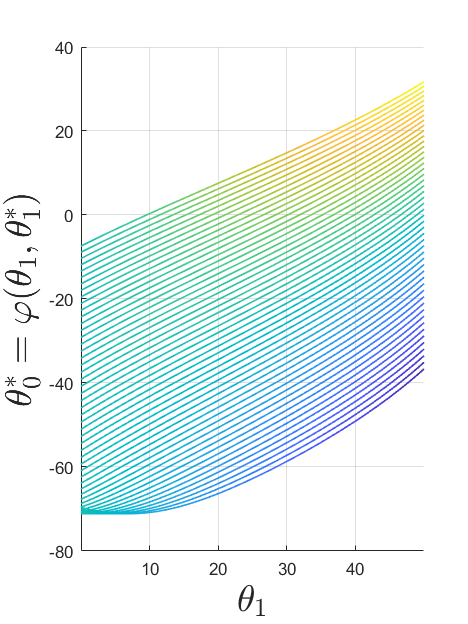

[X,Y] = meshgrid(theta1, theta1_);
C = X.*Y;
f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 9.9, 13.2]);
p = waterfall(theta1, theta1_, theta0_.', C);
p.FaceAlpha = 0;
p.LineWidth = 1;
ylim([theta1_(1) theta1_(end)]);
xlim([theta1(1)+0.01 theta1(end)-0.01]);
view([0 -1 0]); % front-view
xlabel('$\theta_1$', extraInputs{:});
ylabel('$\theta_1^*$', extraInputs{:});
zlabel('$\theta_0^* = \varphi(\theta_1, \theta_1^*)$', extraInputs{:});
exportgraphics(f, 'thumb/figures/theta0--_step12_front.png', 'Resolution', 600);

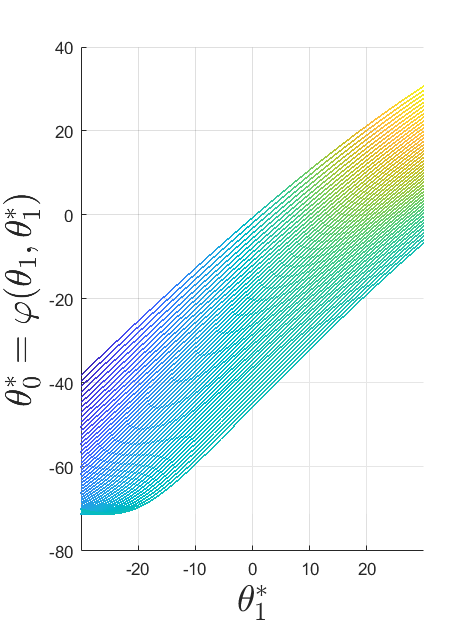

[X,Y] = meshgrid(theta1_, theta1);
C = X.*Y;
f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 9.9, 13.2]);
p = waterfall(theta1_, theta1, theta0_, C);
p.FaceAlpha = 0.02;
p.LineWidth = 1;
xlim([theta1_(1)+0.01 theta1_(end)-0.01]);
ylim([theta1(1)+0.01 theta1(end)-0.01]);
view([0 -1 0]); % front-view
ylabel('$\theta_1$', extraInputs{:});
xlabel('$\theta_1^*$', extraInputs{:});
zlabel('$\theta_0^* = \varphi(\theta_1, \theta_1^*)$', extraInputs{:});
exportgraphics(f, 'thumb/figures/theta0--_step12_right.png', 'Resolution', 600);

### Inversion process

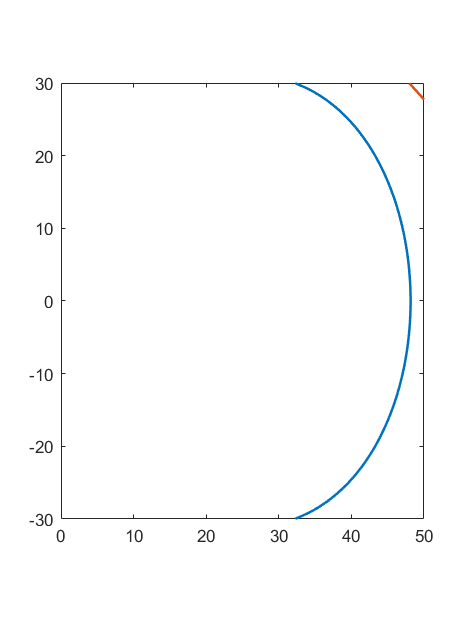

query_theta0_min = min(theta0(:));
query_theta0_max = max(theta0(:));

query_theta0__min = min(theta0_(:));
query_theta0__max = max(theta0_(:));

shift1 = 2;
shift2 = 5;
shift3 = 2;
val_theta0 = linspace(query_theta0_min+shift1,query_theta0_max-shift2,steps);
val_theta0_ = linspace(query_theta0__min+shift3,query_theta0__max-shift3,steps2);
ans_theta1_str = strings([steps, steps2]);
ans_theta1__str = strings([steps, steps2]);
ans_theta1 = NaN * ones([steps, steps2]);
ans_theta1_ = NaN * ones([steps, steps2]);

for i = 1:steps
    for j = 1:steps2
        query_theta0 = val_theta0(i) * ones(steps,steps2);
        query_theta0_ = val_theta0_(j) * ones(steps,steps2);
        
        z1 = theta0;
        z2 = query_theta0;
        zdiff = z1 - z2;
        C2 = contours(theta1, theta1_, zdiff.', [0 0]);
        xL = C2(1, 2:end);
        yL = C2(2, 2:end);
        
        z1_ = theta0_;
        z2_ = query_theta0_;
        zdiff_ = z1_ - z2_;
        C2_ = contours(theta1, theta1_, real(zdiff_.'), [0 0]);
        xL_ = C2_(1, 2:end);
        yL_ = C2_(2, 2:end);
        
        % blue - q_theta0
        % red - q_theta0*
        plot(xL, yL, xL_, yL_, 'LineWidth', 1.5);
        % legend('$q\theta_0$', '$q\theta_0^*$', 'interpreter','latex','fontsize',16);
        % xlabel('$\theta_1$', extraInputs{:});
        % ylabel('$\theta_1^*$', extraInputs{:});
        xlim([theta1(1) theta1(end)]);
        ylim([theta1_(1) theta1_(end)]);
        daspect([1 1 1]);
        
        [x_int, y_int] = intersections(xL, yL, xL_, yL_);
        s = size(x_int);
        
        if isempty(x_int) || isempty(y_int)
            ans_theta1_str(i, j) = "-";
            ans_theta1__str(i, j) = "-";
        elseif (s(1) == 2) || (s(2) == 2)
            ans_theta1_str(i, j) = num2str(x_int(2), '%.2f');
            ans_theta1__str(i, j) = num2str(y_int(2), '%.2f');
            ans_theta1(i, j) = x_int(2);
            ans_theta1_(i, j) = y_int(2);
        else
            ans_theta1_str(i, j) = num2str(x_int, '%.2f');
            ans_theta1__str(i, j) = num2str(y_int, '%.2f');
            ans_theta1(i, j) = x_int;
            ans_theta1_(i, j) = y_int;
        end
        pause(0.001);
    end
end


% query_theta0 = 38 * ones(steps,steps2);
% query_theta0_ = 18.7 * ones(steps,steps2);

% z1 = theta0;
% z2 = query_theta0;
% zdiff = z1 - z2;
% C2 = contours(theta1, theta1_, zdiff.', [0 0]);
% xL = C2(1, 2:end);
% yL = C2(2, 2:end);

% z1_ = theta0_;
% z2_ = query_theta0_;
% zdiff_ = z1_ - z2_;
% C2_ = contours(theta1, theta1_, real(zdiff_.'), [0 0]);
% xL_ = C2_(1, 2:end);
% yL_ = C2_(2, 2:end);

% % blue - q_theta0
% % red - q_theta0*
% f = figure();
% f.WindowState = 'maximized';
% t = tiledlayout(1,1,'Padding','none');
% t.Units = 'centimeters';
% t.OuterPosition = [0, 0, 9.9, 13.2];
% nexttile;
% plot(xL, yL, xL_, yL_, 'LineWidth', 1.5);
% legend('$\bar{\theta}_0$', '$\bar{\theta}_0^*$', 'interpreter','latex','fontsize',16, 'location', 'west');
% xlabel('$\theta_1$', extraInputs{:});
% ylabel('$\theta_1^*$', extraInputs{:});
% xlim([theta1(1) theta1(end)]);
% ylim([theta1_(1) theta1_(end)]);
% daspect([1 1 1]);
% exportgraphics(t, 'thumb/figures/curves f & g (38,18.7).png', 'Resolution', 300);

ans_theta1 = ans_theta1.';
ans_theta1_ = ans_theta1_.';

### Inversion results

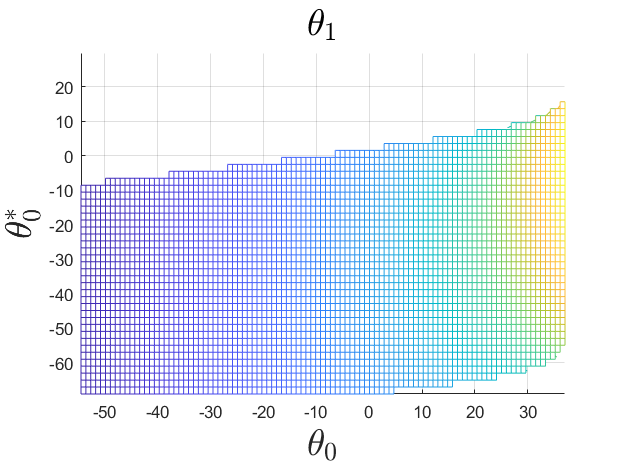

f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 13.2, 9.9]);
meshc(val_theta0, val_theta0_, ans_theta1);
view([0 0 1]); % top-view
xlim([val_theta0(1), val_theta0(end)]);
ylim([val_theta0_(1), val_theta0_(end)]);
xlabel('$\theta_0$', extraInputs{:});
ylabel('$\theta_0^*$', extraInputs{:});
title('$\theta_1$', extraInputs{:});
zlabel('$\theta_1 = f(\theta_0, \theta_0^*)$', extraInputs{:});

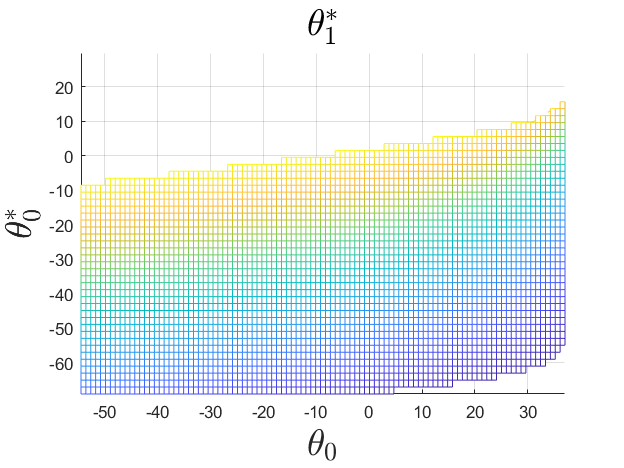


f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 13.2, 9.9]);
meshc(val_theta0, val_theta0_, ans_theta1_);
view([0 0 1]); % top-view
xlim([val_theta0(1), val_theta0(end)]);
ylim([val_theta0_(1), val_theta0_(end)]);
xlabel('$\theta_0$', extraInputs{:});
ylabel('$\theta_0^*$', extraInputs{:});
title('$\theta_1^*$', extraInputs{:});
zlabel('$\theta_1^* = f(\theta_0, \theta_0^*)$', extraInputs{:});

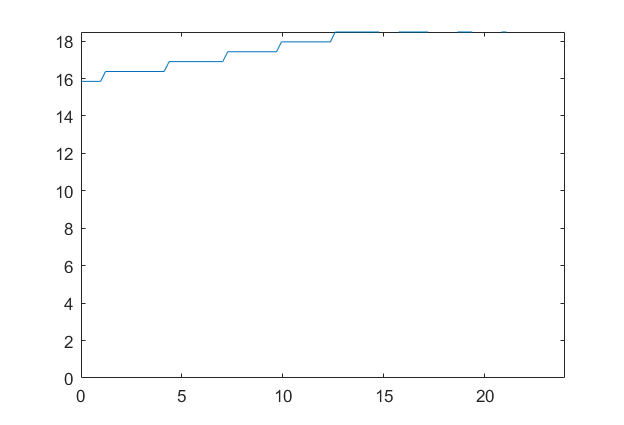


x = val_theta0;
y = [];
y1 = [];
for i = 1:steps
    j = steps2;
    while isnan(ans_theta1(j,i))
        j = j - 1;
    end
    y(i) = val_theta0_(j);
    j = 1;
    while isnan(ans_theta1(j,i))
        j = j + 1;
    end
    y1(i) = val_theta0_(j);
end
f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 13.2, 9]);
y2 = (y - y1) * (pi/180) * 15;
x2 = x * (pi/180) * 15;
x2 = x2 - x2(1) * ones(size(x2));
plot(x2, y2);
ylim([0 y2(end)]);
xlim([x2(1) x2(end)]);

### Other required functions

function p = circle_circle_xz(p1, p2, l1, l2, sgn)
% position analysis in xz plane

% transformation matrix to convert [x; 0; z] to [x; z]
A = [1, 0, 0;
    0, 0, 1];
p1 = A * p1;
p2 = A * p2;

R = sqrt( (p2 - p1).' * (p2 - p1) );
a = (l1^2 - l2^2) / (2 * R^2);
b = 0.5 * sqrt( 2 * (l1^2+l2^2) / R^2 - (l1^2 - l2^2)^2 / R^4 - 1 );

I = [1, 0; 0, 1];
B = [0, -1; 1, 0];

p = A.' * (( 0.5*[I, I] + (-a*I + sgn*b*B)*[I, -I] ) * [p1; p2]);
end

function p = circle_circle_xy(p1, p2, l1, l2, sgn)
% position analysis in xy plane

% transformation matrix to convert [x; y; 0] to [x; y]
A = [1, 0, 0; 0, 1, 0];
p1 = A * p1;
p2 = A * p2;

R = sqrt( (p2 - p1).' * (p2 - p1) );
a = (l1^2 - l2^2) / (2 * R^2);
b = 0.5 * sqrt( 2 * (l1^2+l2^2) / R^2 - (l1^2 - l2^2)^2 / R^4 - 1 );

I = [1, 0; 0, 1];
B = [0, -1; 1, 0];

p = A.' * (( 0.5*[I, I] + (-a*I + sgn*b*B)*[I, -I] ) * [p1; p2]);
end

function R = rot(deg_x, deg_y, deg_z)
Rx = [1, 0, 0, 0;
    0, cos(deg_x), -sin(deg_x), 0;
    0, sin(deg_x), cos(deg_x), 0;
    0, 0, 0, 1];

Ry = [cos(deg_y), 0, -sin(deg_y), 0;
    0, 1, 0, 0;
    sin(deg_y), cos(deg_y), 1, 0;
    0, 0, 0, 1];

Rz = [cos(deg_z), -sin(deg_z), 0, 0;
    sin(deg_z), cos(deg_z), 0, 0;
    0, 0, 1, 0;
    0, 0, 0, 1];

R = Rz * Ry * Rx;
end

function T = trans(trans_x, trans_y, trans_z)
T = [1, 0, 0, trans_x;
    0, 1, 0, trans_y;
    0, 0, 1, trans_z;
    0, 0, 0, 1];
end